# `DEMO_06: `  4-bar linkage analysis** - velocity analysis**

Let's look at another example where we want to compute the velocities of certain points and links of a 4bar mechanism.  We'll follow pretty much the same approach as the one in `DEMO_05_bh_4bar_simple_velocity_analysis.mlx`  .... but we'll use **Passive Rotation Matrices** in our computations.  

Passive rotation marices will allow us to solve the kinematics of a machine in a more "general pose" than the simple/convenient one shown in DEMO_05. 

- For a refresher on passive rotation matrices have a look at Appendix_A at the bottom of this script.  

`Bradley Horton : 24-Jul-2019, bhorton@mathworks.com`

# Our **specific** problem:

**Figure 01:  the 4bar linkage**

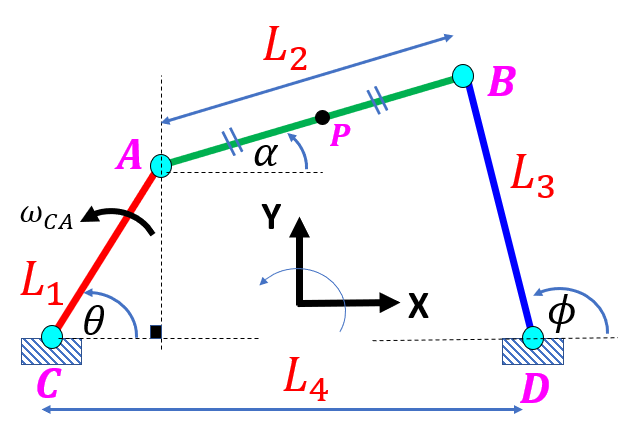

For the instant shown below, compute the following:

- The velocity of point P

- The angular velocity $\omega_{\textrm{DB}}$

where:

- 
$$\begin{array}{l}
L_1 =0\ldotp 4\;\;\;\;,\;\;\;\;L_2 =0\ldotp 7\;\;\;,\;\;\;L_3 =0\ldotp 8\;\;\;\;,L_4 =1\\
\theta_{\deg } =75\;\;\;,\;\;\;\phi_{\deg } =111\ldotp 61\;\;\;,{\;\;\;\alpha }_{\deg } =30\ldotp 70\\
\omega_{\textrm{CA}} =3\;\frac{\textrm{rad}}{\sec }
\end{array}$$


Start with a clean slate and remove any previous assumptions from the Symbolic engine

clear all 

Define our machine's parameters:

syms    theta  phi  alpha           real 
syms L_1  L_2  L_3  L_4             real
syms omega_DB  omega_CA   omega_AB  real

**Define the angular velcity vectors of our 3 links: **

omega_CA_vec = [0;0;omega_CA];
omega_AB_vec = [0;0;omega_AB];
omega_DB_vec = [0;0;omega_DB];

**Compute  **$v_A$** :**

Let's compute the velocity of point A and express it's components in the F1-frame and the G-frame.

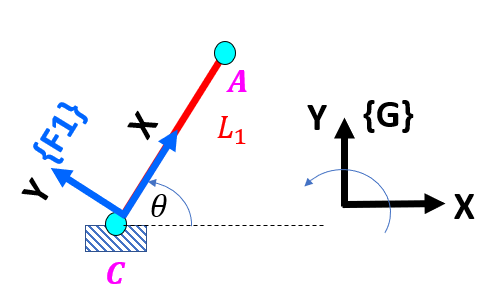

- 
$$^{F1}v_A = \omega_{CA} \enspace \times \enspace ^{F1}r_A$$


-  
$$^{G}v_A = {^G}R_{F1} \enspace . \enspace ^{F1}v_A$$
 

F1_rA          = [L_1;0;0];
F1_v_A_vec     = cross( omega_CA_vec, F1_rA )

$$F1\_v\_A\_vec = \left(\begin{array}{c} 0\\ L_{1}\,\omega_{\mathrm{CA}}\\ 0 \end{array}\right)$$

G_R_F1         = LOC_get_GRB(theta);
G_v_A_vec      = G_R_F1 * F1_v_A_vec

$$G\_v\_A\_vec = \left(\begin{array}{c} -L_{1}\,\omega_{\mathrm{CA}}\,\sin\left(\theta \right)\\ L_{1}\,\omega_{\mathrm{CA}}\,\cos\left(\theta \right)\\ 0 \end{array}\right)$$

**Compute  **$v_B$** :**

Let's compute the velocity of point B and express it's components in the F4-frame and the G-frame.

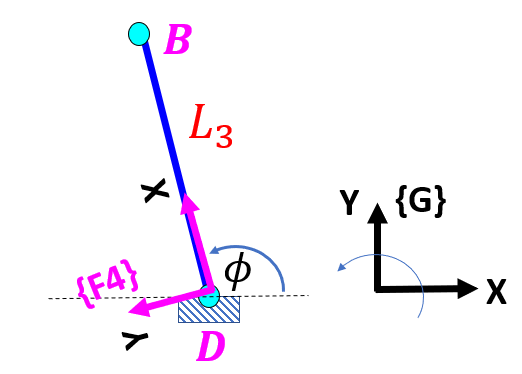

- 
$$^{F4}v_B = \omega_{DB} \enspace \times \enspace ^{F4}r_B$$


-  
$$^{G}v_B = {^G}R_{F4} \enspace . \enspace ^{F4}v_B$$


F4_rB           = [L_3;0;0]; 
F4_v_B_vec      = cross( omega_DB_vec, F4_rB )

$$F4\_v\_B\_vec = \left(\begin{array}{c} 0\\ L_{3}\,\omega_{\mathrm{DB}}\\ 0 \end{array}\right)$$

 G_v_B_vec      = LOC_get_GRB(phi) * F4_v_B_vec;

**Define  **$v_P$** using **$v_A$ **and again using** $v_B$

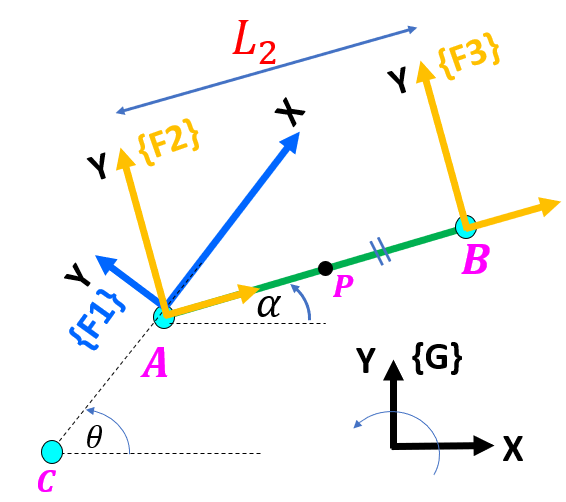

**Using A: **We'll first convert $ ^{G}v_A$ into $ ^{F2}v_A$ and then we'll define $^{F2}v_P$ :

- 
$$^{F2}v_A = {^{F2}R_{G}} \enspace . \enspace ^{G}v_A$$


- 
$$^{F2}v_P \enspace  =  \enspace ^{F2}v_A \quad+ \quad \omega_{AB} \enspace \times \enspace ^{F2}r_P$$


F2_v_A_vec      = LOC_get_bRg(alpha) * G_v_A_vec;
F2_rP           = [(L_2/2);0;0];
F2_v_P_vec      = F2_v_A_vec  +  cross(omega_AB_vec, F2_rP);

**Using B: **We'll first convert $ ^{G}v_B$ into $ ^{F3}v_B$ and then we'll define $^{F3}v_P$ .  While we're at it let's also compute $^{G}v_P$

- 
$$^{F3}v_B = {^{F3}R_{G}} \enspace . \enspace ^{G}v_B$$


- 
$$^{F3}v_P \enspace  =  \enspace ^{F3}v_B \quad+ \quad\omega_{AB} \enspace \times \enspace ^{F3}r_P$$


- 
$$^{G}v_P = {^G}R_{F3} \enspace . \enspace ^{F3}v_P$$


F3_v_B_vec      = LOC_get_bRg(alpha) * G_v_B_vec;
F3_rP           = [(-L_2/2);0;0];
F3_v_P_vec      = F3_v_B_vec  +  cross(omega_AB_vec, F3_rP);
 G_v_P_vec      = LOC_get_GRB(alpha) * F3_v_P_vec;

Since the Frames $\textrm{F2}$ and $\textrm{F3}$ are parallel, we can compare ***velocity vectors*** expressed in each frame.  For example:

- 
$$^{F2}v_P \enspace  = \enspace  ^{F3}v_P \enspace  $$


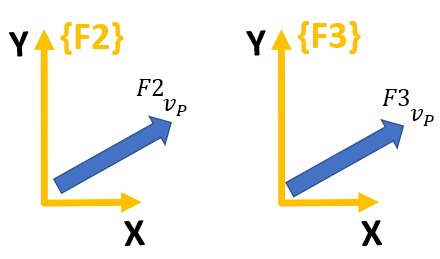

Let's put these 2 vectors side by side so that we can look at them:

%[F2_v_P_vec, F3_v_P_vec]
F2_v_P_vec == F3_v_P_vec

$$ans = \left(\begin{array}{c} L_{1}\,\omega_{\mathrm{CA}}\,\sin\left(\alpha \right)\,\cos\left(\theta \right)-L_{1}\,\omega_{\mathrm{CA}}\,\cos\left(\alpha \right)\,\sin\left(\theta \right)=L_{3}\,\omega_{\mathrm{DB}}\,\cos\left(\varphi \right)\,\sin\left(\alpha \right)-L_{3}\,\omega_{\mathrm{DB}}\,\cos\left(\alpha \right)\,\sin\left(\varphi \right)\\ \frac{L_{2}\,\omega_{\mathrm{AB}}}{2}+L_{1}\,\omega_{\mathrm{CA}}\,\cos\left(\alpha \right)\,\cos\left(\theta \right)+L_{1}\,\omega_{\mathrm{CA}}\,\sin\left(\alpha \right)\,\sin\left(\theta \right)=L_{3}\,\omega_{\mathrm{DB}}\,\cos\left(\alpha \right)\,\cos\left(\varphi \right)-\frac{L_{2}\,\omega_{\mathrm{AB}}}{2}+L_{3}\,\omega_{\mathrm{DB}}\,\sin\left(\alpha \right)\,\sin\left(\varphi \right)\\ 0=0 \end{array}\right)$$

When you look at the expressions above, remember that we have been given numeric values for $\left\lbrack L_1 ,\;L_2 ,\;L_3 ,\;L_4 ,\theta ,\alpha ,\;\phi \;,\;\omega_{\textrm{CA}} \right\rbrack$. 

- So ? - So, the only UNknowns in the above 2 equations are $\omega_{\textrm{DB}}$ and $\omega_{\textrm{AB}}$.

So we have 2 equations with 2 UNknowns ... which we know how to solve.

EQ_P    = F2_v_P_vec == F3_v_P_vec;
THE_SOL = solve(EQ_P, [omega_AB, omega_DB])

THE_SOL = struct with fields:
    omega_AB: [1×1 sym]
    omega_DB: [1×1 sym]


So $\omega_{\textrm{AB}}$ and $\omega_{\textrm{DB}}$ are:

[THE_SOL.omega_AB,  THE_SOL.omega_DB].'

$$ans = \left(\begin{array}{c} \frac{L_{1}\,\omega_{\mathrm{CA}}\,\cos\left(\varphi \right)\,{\sin\left(\alpha \right)}^{2}\,\sin\left(\theta \right)-L_{1}\,\omega_{\mathrm{CA}}\,{\sin\left(\alpha \right)}^{2}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)+L_{1}\,\omega_{\mathrm{CA}}\,{\cos\left(\alpha \right)}^{2}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)-L_{1}\,\omega_{\mathrm{CA}}\,{\cos\left(\alpha \right)}^{2}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)}{L_{2}\,\left(\cos\left(\alpha \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\alpha \right)\right)}\\ \frac{L_{1}\,\omega_{\mathrm{CA}}\,\cos\left(\alpha \right)\,\sin\left(\theta \right)-L_{1}\,\omega_{\mathrm{CA}}\,\sin\left(\alpha \right)\,\cos\left(\theta \right)}{L_{3}\,\cos\left(\alpha \right)\,\sin\left(\varphi \right)-L_{3}\,\cos\left(\varphi \right)\,\sin\left(\alpha \right)} \end{array}\right)$$

Once we have solved for $\omega_{\textrm{AB}}$ and $\omega_{\textrm{DB}}$, we can now revisit one of our equations for $v_P$ and then compute $v_P$, eg:

G_v_P_vec

$$G\_v\_P\_vec = \begin{array}{l} \left(\begin{array}{c} -\cos\left(\alpha \right)\,\left(L_{3}\,\omega_{\mathrm{DB}}\,\cos\left(\alpha \right)\,\sin\left(\varphi \right)-L_{3}\,\omega_{\mathrm{DB}}\,\cos\left(\varphi \right)\,\sin\left(\alpha \right)\right)-\sin\left(\alpha \right)\,\sigma_{1}\\ \cos\left(\alpha \right)\,\sigma_{1}-\sin\left(\alpha \right)\,\left(L_{3}\,\omega_{\mathrm{DB}}\,\cos\left(\alpha \right)\,\sin\left(\varphi \right)-L_{3}\,\omega_{\mathrm{DB}}\,\cos\left(\varphi \right)\,\sin\left(\alpha \right)\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\omega_{\mathrm{DB}}\,\cos\left(\alpha \right)\,\cos\left(\varphi \right)-\frac{L_{2}\,\omega_{\mathrm{AB}}}{2}+L_{3}\,\omega_{\mathrm{DB}}\,\sin\left(\alpha \right)\,\sin\left(\varphi \right) \end{array}$$

# Solve with numeric values:

OK: Let's plug in some NUMERIC values into our derived expressions.

where:

- 
$$\begin{array}{l}
L_1 =0\ldotp 4\;\;\;\;,\;\;\;\;L_2 =0\ldotp 7\;\;\;,\;\;\;L_3 =0\ldotp 8\;\;\;\;,L_4 =1\\
\theta_{\deg } =75\;\;\;,\;\;\;\phi_{\deg } =111\ldotp 61\;\;\;,{\;\;\;\alpha }_{\deg } =30\ldotp 70\\
\omega_{\textrm{CA}} =3\;\frac{\textrm{rad}}{\sec }
\end{array}$$


: Did you use the `bh_4bar_explore_app `to determine the link angles $\left\lbrack \phi \;,\alpha \right\rbrack$ for your specified link LENGTHS

my_theta    =  deg2rad(75);         % rad
my_phi      =  deg2rad(111.61);     % rad
my_alpha    =  deg2rad(30.70);      % rad
my_omega_CA = 3; % rad/sec
my_L1       = 0.4;  % m
my_L2       = 0.7;  % m
my_L3       = 0.8;  % m
my_L4       = 1;  % m
my_num_list = [my_L1, my_L2, my_L3, my_theta, my_phi, my_alpha, my_omega_CA];
my_sym_list = [  L_1,   L_2,   L_3,    theta,    phi,    alpha,    omega_CA];

OK, let's compute 

- $\omega_{\textrm{AB}}$   ,   $\omega_{\textrm{DB}}$   ,   $^{G}v_P $

my_omega_AB = double( subs(THE_SOL.omega_AB, my_sym_list, my_num_list)  ) 

my_omega_AB = -1.0353

my_omega_DB = double( subs(THE_SOL.omega_DB, my_sym_list, my_num_list)  )               

my_omega_DB = 1.0609

my_v_P      = double( subs(G_v_P_vec, [my_sym_list,    omega_AB,    omega_DB], ...
                                      [my_num_list, my_omega_AB, my_omega_DB])  )   

my_v_P =    -0.9741
   -0.0010
         0


# Extra credit:     Checking again using our derived **Jacobians**

In `DEMO_04_explore_jacobs.mlx` we derived expressions for the Jacobians and angular rates for the 4bar mechanism.  

- 
$$\left\lbrack \begin{array}{c}
\phi^˙ \\
\alpha^˙ 
\end{array}\right\rbrack \;\;=\;\;\;\left\lbrack \begin{array}{c}
\frac{\partial \phi }{\partial \theta }\\
\frac{\partial \alpha }{\partial \theta }
\end{array}\right\rbrack \ldotp \theta^˙ \;\;$$


where the Jacobians can be written as:

- 
$$\left\lbrack \begin{array}{c}
\frac{\partial \phi }{\partial \theta }\\
\frac{\partial \alpha }{\partial \theta }
\end{array}\right\rbrack \;\;=\;\;\;\frac{1}{L_3 \ldotp L_2 \ldotp \sin \left(\phi \right)\ldotp \cos \left(\alpha \right)-L_3 \ldotp L_2 \ldotp \cos \left(\phi \right)\ldotp \sin \left(\alpha \right)}\ldotp \left\lbrack \begin{array}{cc}
-L_2 \ldotp \cos \left(\alpha \right) & -L_2 \ldotp \sin \left(\alpha \right)\\
-L_3 \ldotp \cos \left(\phi \right) & -\;L_3 \ldotp \sin \left(\phi \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{-L}_1 \ldotp \sin \left(\theta \right)\\
\;\;L_1 \ldotp \cos \left(\theta \right)
\end{array}\right\rbrack$$


And we implemented these equations into the function called `calc_phi_alpha_jacobs()` . 

So? - So we can use these Jacobians to check the answers that we previously computed for $\omega_{\textrm{DB}} \;\left(\equiv \phi^˙ \right)$ and $\omega_{\textrm{AB}}$ $\left(\equiv \alpha^˙ \right)$.

[E_dphi_dtheta, E_dalpha_dtheta] = ...
       calc_phi_alpha_jacobs(my_L1, my_L2, my_L3, my_theta, my_phi, my_alpha);
   
should_be_omega_AB =  E_dalpha_dtheta  * my_omega_CA;
should_be_omega_DB =  E_dphi_dtheta    * my_omega_CA;

And comparing we get:

[ should_be_omega_DB,   should_be_omega_AB;
         my_omega_DB,          my_omega_AB;   
]

ans =     1.0609   -1.0353
    1.0609   -1.0353


# Next steps - a kinematic model in **Simulink**

Let's use Simulink to validate our hand calculations

tf_open_model   = true;                                        

#### The INITIAL joint angles:

theta_0_rad     = my_theta;
phi_0           = my_phi;

#### The known INITIAL joint velocity:

theta_dot_0_rad = my_omega_CA;

#### Define parameters needed by Simscape model:

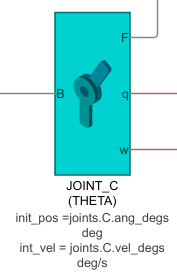    and   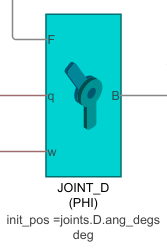

joints.C.ang_degs = rad2deg(theta_0_rad);
joints.C.vel_degs = rad2deg(theta_dot_0_rad);
joints.D.ang_degs = rad2deg(phi_0);

And some more parameters that the Simscape model needs:

density = 1000; % kg/m3
H       = my_L1/10;  % m
W       = my_L1/100; % m 
g       = 9.81;   % m/s^2

#### Open the model and explore:

if(true==tf_open_model)
    THE_MODEL = 'bh_4bar_model_matrix_VEL_ANALYSIS';
    open_system(THE_MODEL);
    
    % set the simulation STOP time to ZERO
    set_param(THE_MODEL,'StopTime', '0');
end      

#### Run the Simulink model:

You can run the Simulink model by pushing the Run button(shown below):

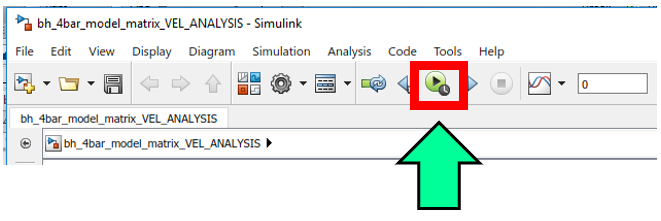

Note how the Simulink model confirms our previous computations:

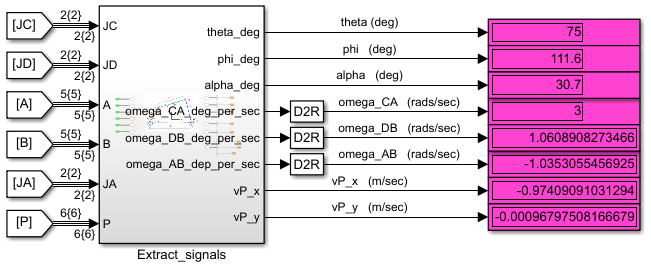

Recall our previous computations:

[rad2deg([my_theta; my_phi; my_alpha]);  my_omega_CA; my_omega_DB;  my_omega_AB;  my_v_P]

ans =    75.0000
  111.6100
   30.7000
    3.0000
    1.0609
   -1.0353
   -0.9741
   -0.0010
         0


# Local functions only beyond this point

# **Appendix_A:  **PASSIVE rotation matrices

Consider the following scenario: 

- We have a data point $P$.

- We have a fixed frame called the **G-fame.**

- We know the *(x,y) *co-ordinates of the point $P$ in this **G-fame** and refer to this as ${^GP}$.

- We then rotate the **B-frame** by $\theta$ relative to the fixed **G-frame**. 

We now want to know what the co-ordinate of the point $P$ is relative to this new **B-frame, **ie: what is ${^BP}$ ?  This scenario is shown in the figure below:

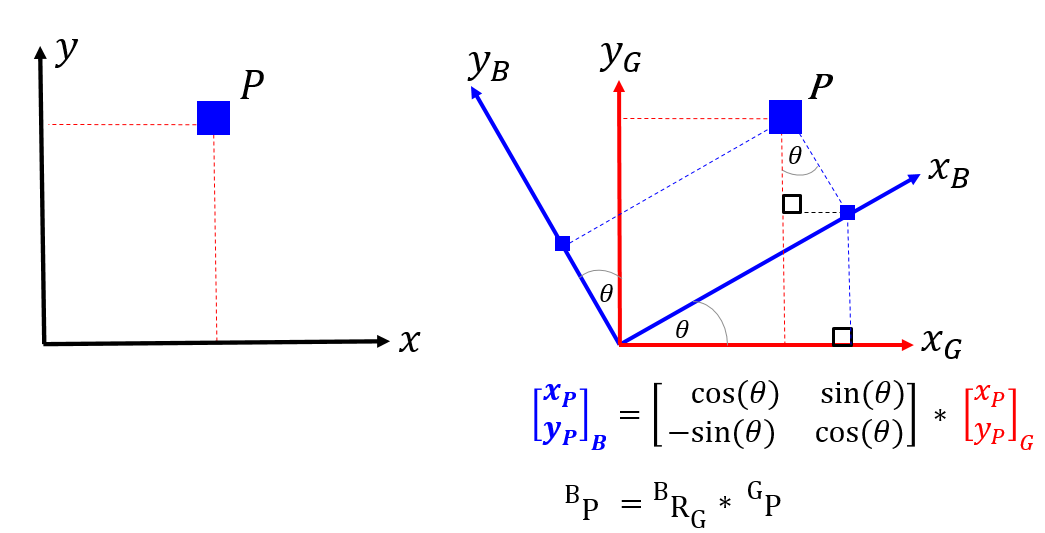 

A **PASSIVE** rotation matrix, converts the co-ordinates of a point expressed in a fixed **G-frame**, into the co-ordinates of the same point expressed in the new **B-frame**.

 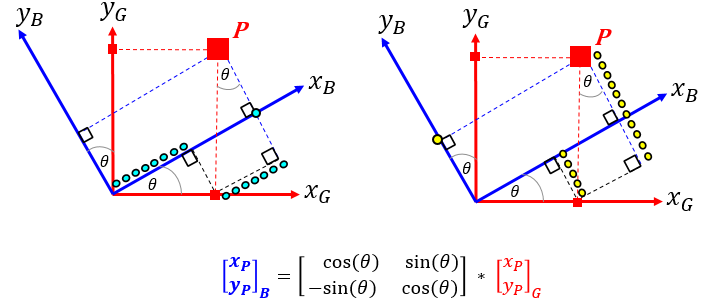

**ATTENTION:   **In the 2 functions below, $\theta$ represents the position of the B-frame relative to the fixed G-frame.

#### Define:  $^BR_G$  such that     $^BP = {^BR_G} .^GP$

function bRg = LOC_get_bRg(th)

         bRg = [ cos(th), sin(th),  0;
                -sin(th), cos(th),  0;
                       0,       0,  1 ];
end

####  Define:  $^GR_B$   such that     $^GP = {^GR_B} .^BP$

function GRB = LOC_get_GRB(th)

         GRB = [ cos(th), -sin(th),  0;
                 sin(th),  cos(th),  0;
                       0,        0,  1 ];
end

**NOTE:**

- We'll use the REAL declaration for our SYMBOLIC symbols AND the standard MATLAB `cross` function

- The local code snippet commented out below is not needed

% function c = cross(a,b)
% 
%     c1 = a(2).*b(3)-a(3).*b(2);
%     c2 = a(3).*b(1)-a(1).*b(3);
%     c3 = a(1).*b(2)-a(2).*b(1);
% 
%     c  = [c1;c2;c3]; 
% 
% end
% 